# **LAB 5 - MICROARRAYS**

**ES 1 - Preprocessing di dati da Microarray a due canali**

*1. Import data corresponding to the two channels of a cDNA microarray experiment (microdata.mat) and visualize them.*

*• derive signal-background intensities for the two channels*

*• remove bad quality spots, deleting elements for which the flag value is -50*

*• remove negative values*

*• draw a log2(R) vs log2(G) plot*

*• draw an MA plot*

*• draw an MA plot using the Matlab function mairplot*

*• apply a lowess normalization*

I dati in `microdata.mat` sono così classificati:

- `Gsig `e `Rsig `contengono i valori del segnale per il channel rosso e verde, comprensivi del background noise

- `Gbkg `e `Rbkg `contengono i valori del background noise per entrambi i canali, che dovranno essere rimossi

- `flags `segnala ulteriori valori da non tenere in considerazione

load('microdata.mat');

Vengono rimossi i segnali di background dai segnali totali, in modo tale da ottenere segnali che contengano solamente informazione relativa alla quantità di trascritto legato.

R = Rsig - Rbkg;
G = Gsig - Gbkg;

Segnaliamo gli eventuali negativi, ottenuti da valori di rumore di fondo troppo elevati. Segnaliamo anche i valori identificati da `flags `(indicati con -50). Salviamo tutti questi indici all'interno di `to_remove.`

negvalueR = find(R<0);
negvalueG = find(G<0);
negvalue = union(negvalueR, negvalueG);
negquality = find(flags==-50);
to_remove = union(negvalue, negquality);

Rimuoviamo effettivamente dai vettori `R` e` G` gli elementi identificati da `to_remove, `impostandoli a `[].`

R(to_remove) = [];
G(to_remove) = [];

Controlliamo la necessità di una normalizzazione attraverso uno **scatterplot. **Sugli assi poniamo la distribuzone dell'intensità di espressione dei channels R e G in scala logaritmica in base 2. Se i geni fossero ugualmente trascritti nei due campioni, la distribuzione aderirebbe alla bisettrice del quadrante: al contrario, sbilanciamenti a destra o a sinistra della linea diagonale indicano una differente manifestazione del gene nei differenti canali.

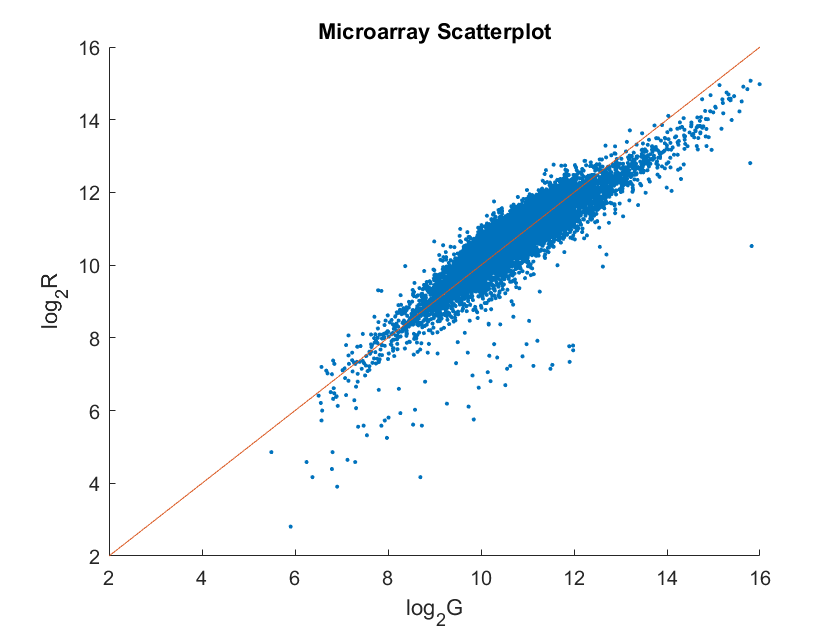

figure
scatter(log2(G), log2(R),'.');
xlabel('log_2G');
ylabel('log_2R');
title('Microarray Scatterplot')
hold on
plot([2 16], [2 16]);

Visualizziamo ora l'MA plot, o **plot di Bland-Altman, **che permette di visualizzare se è possibile effettuare considerazioni o se sono necessarie operazioni di normalizzazione dei dati per elimiare i bias intriseci all'asset sperimentale. Questo plot ha sulle ascisse $M=\log_{2\;} \sqrt{\left(R\cdot G\right)\;\;}$, ovvero la semisomma dei logaritmi dei due canali indicativa dell'intensità logaritmica media, $A=\log_{2\;} \frac{R}{G}$ sulle ordinate, ovvero un coefficiente di correlazione tra i due canali R e G.

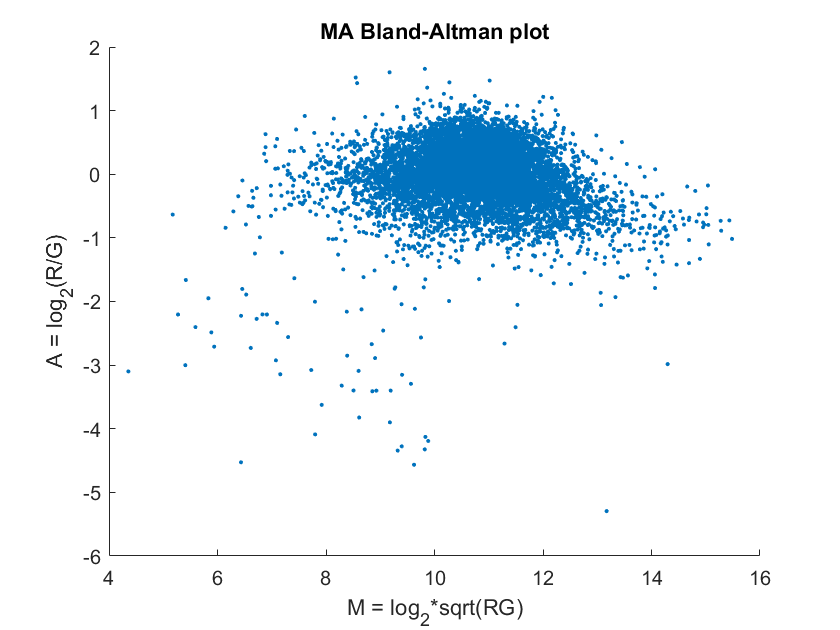

figure
scatter(0.5*log2(R.*G), log2(R./G), '.');
xlabel('M = log_2*sqrt(RG)');
ylabel('A = log_2(R/G)');
title('MA Bland-Altman plot')

Dal momento che si vuole effettuare un'analisi differenziale dei due trascrittomi, è necessario normalizzare l'MA plot così da farlo giacere perfettamente sulla linea dello zero; ulteriori deviazioni da questa baseline non sono informazioni rilevanti dal punto di vista biologico. La normazione utilizzata è quella di tipo **LOWESS.**

`mairplot `estrae i valori delle coordinate del MA plot, da passare alla funzione `malowess` che fornisce un vettore che contiene i valori della curva di regressione ottenuta, che andranno sottratti a quelli originali

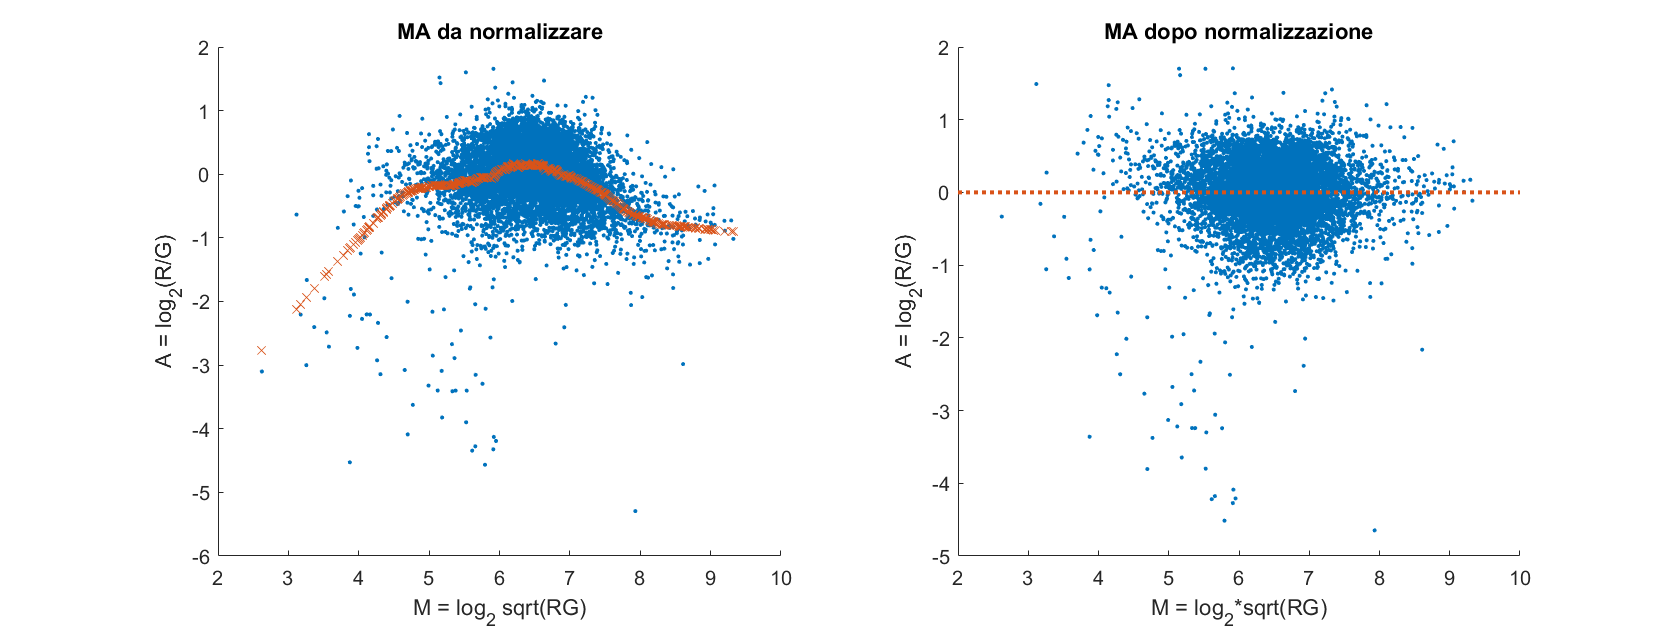

[x, y] = mairplot(R,G,'SHOWPLOT',false);
y_lowess = malowess(x,y);
ynorm = y-y_lowess;

hhfigure
subplot(121);
scatter(x,y,'.'); 
hold on
plot(x,y_lowess, 'x')
xlabel('M = log_2 sqrt(RG)');
ylabel('A = log_2(R/G)');
title('MA da normalizzare');
subplot(122);
scatter(x, ynorm, '.')
hold on
plot([2 10], [0 0], ':', 'LineWidth',2);
xlabel('M = log_2*sqrt(RG)');
ylabel('A = log_2(R/G)');
title('MA dopo normalizzazione');
xlabel('M = log_2*sqrt(RG)');
ylabel('A = log_2(R/G)');

Successivamente alla normalizzazione lowess, lo scatterplot è uniformemente distribuito attorno alla linea dello zero, e le differenze evidenziate dal discostamento dei punti da questa linea sono esclusivamente di carattere biologico e significativo.

**ES2 - Preprocessing di dati da Microarray a oligonucleotide**

*Import gene expression data (affydata.mat) obtained using an Affymetrix oligonucleotide microarray concerning an experiment on 42 tumor tissues of the central nervous system.*

*• Visualize the intensity distribution histogram and the estimated background adjustment of a specific chip*

*• Use quantilenorm to normalize the background adjusted PM intensities in the CNS data*

*• Draw the boxplots for the PM intensity distributions of the first four chips applying RMA: raw data, data after background adjustment and after quantile normalization.*

*• Use rmasummary to summarize probe intensities of each probe set across multiple chips. Plot the expression of the probesets 3500, 4221 across the 42 samples.*

All'interno di `affydata.mat `sono presenti:

- `PMIntensities `contiene i valori delle intensità di Perfect Match. E' un vettore di tipo *NUM_PROBESxNUM_CHIPS*

- `MMIntensities `contiene i valori delle intensità di MisMatch. E' un vettore di tipo *NUM_PROBESxNUM_CHIPS*

- `CELNames `contiene i nomi dei trascrittomi applicati ai relativi chips

- `ProbeIndeces `indica a quale probeset appartiene ogni probe

load("affydata.mat");

In questo caso non è disponibile un dato che fornisce informazoni sulla distribuzion del background noise. La funzione MATLAB `rmabackadj `permette di rimuoverlo in modo automatizzo stimandone la densità dalle intensità di PM. `pm_bkgadj `contiene quindi il segnale utile già pulito dal rimore di background.

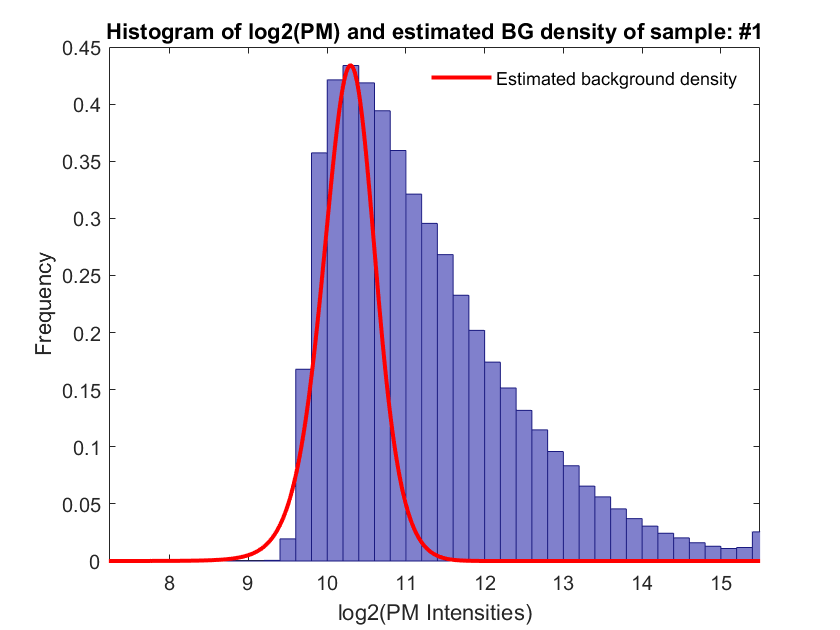

pm_bkgadj = rmabackadj(probeData.PMIntensities,'showplot',1); % Impiega molto tempo

In questo caso, il tipo di normalizzazione utilizzata è la **normalizzazione quantile** `quantilenorm, `che richiede in ingresso direttamente i valori delle intensità di PM 

pm_norm = quantilenorm(pm_bkgadj);

Si visualizzano ora le distribuzioni di intensità di PM per i primi 4 chips attraverso dei boxplot per il dato RAW, quello dopo la rimozione del background noise e quello dopo la normalizzazione quantile. 

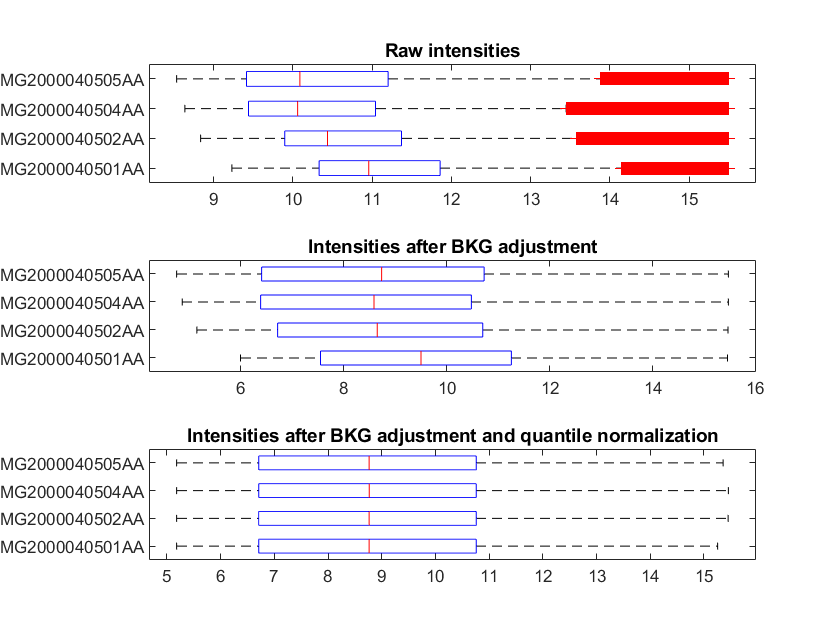

figure
subplot(311);
maboxplot(log2(probeData.PMIntensities(:,1:4)), probeData.CELNames(1:4), 'orientation','horizontal');
title('Raw intensities')
subplot(312);
maboxplot(log2(pm_bkgadj(:,1:4)), probeData.CELNames(1:4), 'orientation','horizontal');
title('Intensities after BKG adjustment')
subplot(313);
maboxplot(log2(pm_norm(:,1:4)), probeData.CELNames(1:4), 'orientation','horizontal');
title('Intensities after BKG adjustment and quantile normalization')

I boxplot del dato RAW mostra un elevato numero di outliers dovuto alla presenza del rumore di background, che poi viene rimosso allo step successivo. Tuttavia, le distribuzioni prima della normalizzazione quantile hanno momenti statistici differenti: questo metodo rende tutte le distribuzioni confrontabili, avendo lo stesso valore medio e la stessa deviazione standard.

Accorpiamo ora i valori appartenenti allo stesso probeset con `rmasummary`, basandosi sugli indici contenuti in `ProbeIndices `e plottiamo l'espressione dei probeset numero 3500 e 4221.

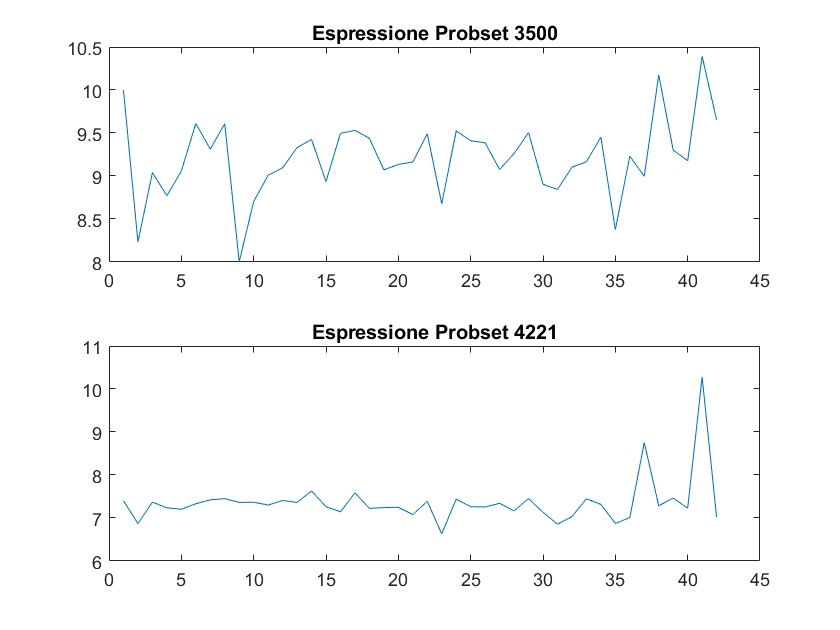

pm_summ = rmasummary(probeData.ProbeIndices, pm_norm);
figure
subplot(211);
plot(pm_summ(3500,:));
title('Espressione Probset 3500');
subplot(212);
plot(pm_summ(4221,:));
title('Espressione Probset 4221');

**ES3 - Analisi differenziale**

*Consider a gene expression profiling experiment on breast cancer samples.*

*Identify the upregulated genes (Bonferroni corrected pvalue<0.05) in stromal samples compared to non-stromal samples.*

*• retrieve the gene expression data set GSE5847 from NCBI GEO [http://www.ncbi.nlm.nih.gov/geo/]*

*• import the data set in Matlab:*

*gseData = geoseriesread('GSE5847_series_matrix.txt')*

*• use mattest for the differential analysis*

*• draw a volcano plot (mavolcanoplot) and select from the interface the list of the upregulated genes (Bonferroni corrected pvalue<0.05).*

Si carica il GEOseries con la funzione `geoseriesread. `

gsedata = geoseriesread('GSE5847_series_matrix.txt');

In questi dati sono presenti campioni ottenuti da tessuto stromale e da tessuto epiteliale. `stroma_idx `indica quali dei campioni presenti nel dataset sono di tipo stromale: per costruire `stroma_idx `individuiamo le stringhe identificative delle due categorie e le confrontiamo con `strcmp.`

samplesources = unique(gsedata.Header.Samples.source_name_ch1);
stroma_idx = strcmp(gsedata.Header.Samples.source_name_ch1, samplesources{1});
epit_idx = strcmp(gsedata.Header.Samples.source_name_ch1, samplesources{2});

Effettuiamo ora il **t-test **con `mattest. `Questa funzione chiede in ingresso i campioni delle due categorie e restituisce un vettore di *p-values *per ogni gene.

pvalues = mattest(gsedata.Data(:,stroma_idx),gsedata.Data(:,epit_idx));

I risultati del T-test sono visualizzabili con un **VulcanoPlot, **ottenuto con `mavolcanoplot.`

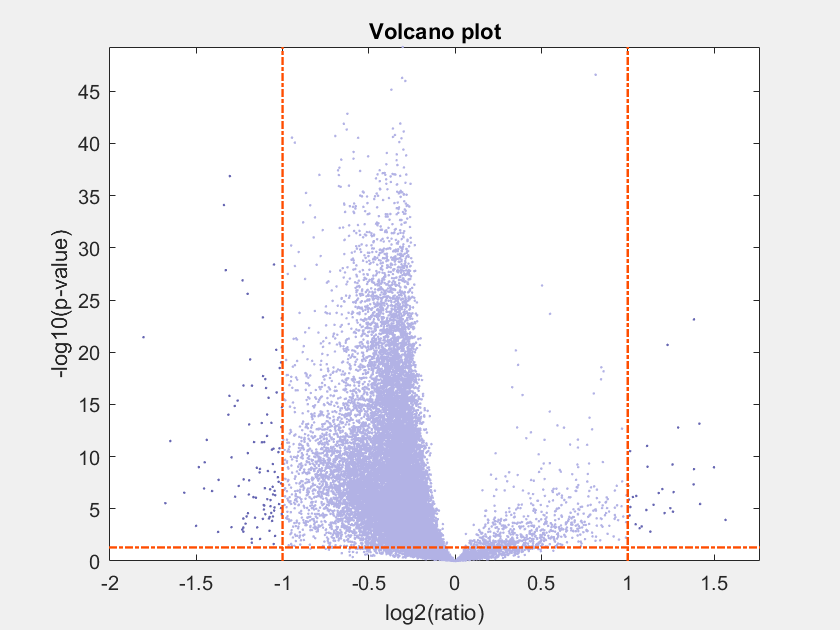

mavolcanoplot(gsedata.Data(:,stroma_idx),gsedata.Data(:,epit_idx), pvalues,'PLOTONLY',true);
title('Volcano plot');

Ogni punto del volcanoplot è rappresentativo di un gene. Sull'asse delle ascisse è presente il **fold change **(logaritmo in base 2 del rapporto): per i geni con fold change superiore a uno (a destra del secondo asse verticale) l'espressione è doppia nei samples stromali rispetto a quelli epiteliali, al contrario i geni con fold change inferiore a -1 (a sinistra del primo asse verticale) l'espressione è doppia nei samples epiteliali. In ordinata è invece presente $-\log_{10\;} \left(\textrm{pvalue}\right)$: tanto più questo valore è alto e tanto più è significativo il risultato sperimentale del test (p-value basso). 

La soglia di *p-value *usata è la soglia standard pari a 0.05: questa soglia è corretta solo nel caso in cui si effettua un solo test statistico. Nel caso di test statistici multipli e in gran numero (per cui è molto probabile ricavare significatività) si effettua una **correzione del *****p-value ***con la **correzione da test multiplo **o **correzione di Bonferroni. **Questo è il metodo più stringente, che riduce più di tutti il numero di falsi positivi. Questa correzione propone di correggere ogni *p-value *moltiplicandolo per il numero di test effettuati. 

pvalues_bonf = pvalues*size(pvalues,1);

Viene rifatto il `volcanoplot `con i *p-values *aggiornati

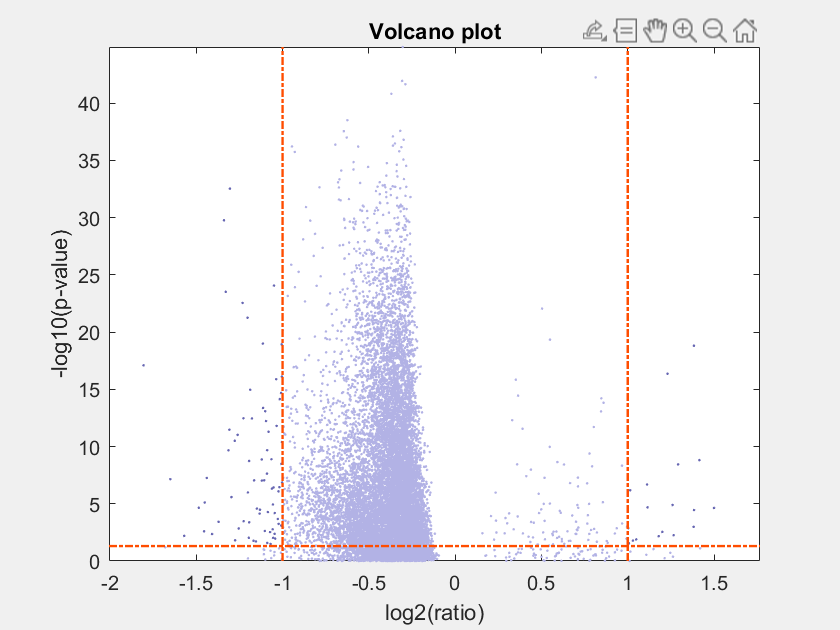

mavolcanoplot(gsedata.Data(:,stroma_idx),gsedata.Data(:,epit_idx), pvalues_bonf,'PLOTONLY',true);
title('Volcano plot');

Tutti i geni sono stati riscalati verso il basso, quindi meno casi sono significativi. In alternativa è possibile analizzare il volcanoplot con i *p-values *non corretti con il metodo Bonferroni, ma utilizzare una soglia differente (inferiore) pari a $0\ldotp 05\cdot N_{\textrm{test}}$